# Preparación parcial: 

comp=tf('s');
num=[1 2];
den=[1 0 30 15];
fdt=tf(num,den)

fdt =
 
       s + 2
  ---------------
  s^3 + 30 s + 15
 
Continuous-time transfer function.
Model Properties


[matrizA,matrizB,matrizC,matrizD] = tf2ss(num,den);
A=matrizA

A =      0   -30   -15
     1     0     0
     0     1     0


B=matrizB

B =      1
     0
     0


C=matrizC

C =      0     1     2


D=matrizD

D = 0

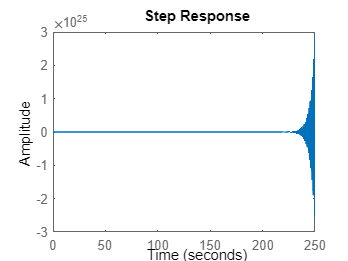

step(fdt)

%%%%%%%Determinacion de controlabilidad y observabilidad%%%%%%
M=[B,A-B]

M =      1    -1   -31   -16
     0     1     0     0
     0     0     1     0


N=[C;C*A]

N =      0     1     2
     1     2     0


n=rank(A)

n = 3

RM= rank(M)

RM = 3

RN= rank(N)

RN = 2

if RM==n
    controlable=1
else
    controlable=0
end

controlable = 1

if RN==n
    observable=1
else
    observable=0
end

observable = 0

## *Punto 1: PID discreto*

Gct1 = pidtune(fdt,'PID') %Usar pidtool

Gct1 =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 156, Ki = 248, Kd = 24.6
 
Continuous-time PID controller in parallel form.
Model Properties


Hd = c2d(fdt,0.0001,'foh')

Hd =
 
  1.667e-09 z^3 + 5.001e-09 z^2 - 4.999e-09 z - 1.667e-09
  -------------------------------------------------------
                   z^3 - 3 z^2 + 3 z - 1
 
Sample time: 0.0001 seconds
Discrete-time transfer function.
Model Properties


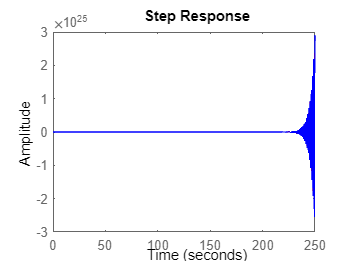

step(fdt,'-r',Hd,'b')

## *Punto 2: Diseñar retro con observador*

%U vector
t_est=100;
zitaobser = 0.8;
tsobser = t_est/10; %Debe ser 10 veces menor al del controlador 
wno = 4/(zitaobser*tsobser);
podeseadoobserva = [1 2*zitaobser*wno]

podeseadoobserva =     1.0000    0.8000


phiAtob = podeseadoobserva(1)*(A')+...
    podeseadoobserva(2)*eye(n);
Ninv=(N^(-1));

Error using  ^ 
Incorrect dimensions for raising a matrix to a power. Check that the matrix is square and the power is a scalar. To operate on each element of the matrix individually, use POWER (.^) for elementwise power.

ke = phiAtob*Ninv*[0;1]
%Integrador adicional
zitadesecont = 0.8;
tsdesecont = t_est/10;
wndcont = 4/(zitadesecont*tsdesecont);
Aempa = [A,[0;0]; -C,0]
Bempa = [B;0]
pdeseadocontrolador = conv([1 2*zitadesecont*wndcont],...
    [1 (200*zitadesecont*wndcont)])
phiAemp=(Aempa^2)+...
    pdeseadocontrolador(2)*(Aempa)+...
    pdeseadocontrolador(3)*eye(n+1)
kemp = [0 0 1]*inv([Bempa Aempa*Bempa (Aempa^2)*Bempa])*phiAemp
k12 = [kemp(1:2)]
ki = -kemp(3)

## Punto 3: Diseñar retro discreto con observador

zitadesecontdis=0.8;
tssdesecontdis=15;
wdcontdis=4/(zitadesecontdis*tssdesecontdis);
ws=20*wdcontdis
TM=(2*pi)/ws

[m,n]=size(A)

syms z s t
G1=(s*eye(n)-A)
G2= inv(G1)
GT= ilaplace(G2)
G3=(subs(GT,t,TM)) %% Matriz A
G=vpa(G3)
H=vpa(int(GT,0,TM)*B) %% Matriz B
%%%%%%% Determinacion de controlabilidad y observabilidad %%%%%%
Md=[H,G*H]
Nd=[C;C*G]
n= rank(G)
RM= rank(Md)
RN= rank(Nd)
if RM==n
    controlable=1
else
    controlable=0
end
if RN==n
    observable=1
else
    observable=0
end

magpolodeseado=exp(((2*pi*zitadesecontdis)/...
    sqrt(1-zitadesecontdis^2))*(wdcontdis/ws))

angdeseado= 2*pi*(wdcontdis/ws)

[real,imag] =pol2cart(magpolodeseado,angdeseado)
polodeseado=real+i*imag
polodeseadoconj=real-i*imag
pdeseadocontroladordis=conv(conv(conv([1 -polodeseado],[1 -polodeseadoconj]),...
    [1 0.0005]),[1 0.0005])
Gempa=[G, [0;0];C*G,1]
Hempa= [H; C*H]

phiGemp=(Gempa^3)+...
    pdeseadocontroladordis(2)*(Gempa^2)+...
    pdeseadocontroladordis(3)*(Gempa)+...
    pdeseadocontroladordis(4)*eye(n+1)
kempdis=[0 0 1]*inv([Hempa Gempa*Hempa (Gempa^2)*Hempa])*phiGemp
k13dis=kempdis(1:2)
kidis=kempdis(3)

%%%%%%%%%%%% Observador de estados en discreto %%%%%%%%%%%%%%%%%%
k13ev=eval(k13dis)
kiev=eval(kidis)
H1= eval(H)
polinomiodeseaobservadis=z^(n)
phiGobser=G^(n)
Ninvv=(Nd^(-1))
kedis = eval(phiGobser*Ninvv*[0;1])
Gev=eval(G)

## *Punto 4: Diseñar compensador lead-led*

## *MP=70° y Oshoot=10%*

% sisotool(fdt) %Programa para hacer el compensador
% Value:  
%   253.35 (s+0.003499)
%   -------------------
%            s
num1=253.35*(s+0.003499);
den1=s;
comp=num1/den1
comp1=eval(comp)
gc=tf([18.431 197.02739], [1 0])
step(gc)